# Working with Image Data

Loading images of Orion Nebula

img1 = imread("OrionNebula1.png");
img2 = imread("OrionNebula2.png");
img3 = imread("OrionNebula3.png");
img4 = imread("OrionNebula4.png");
img5 = imread("OrionNebula5.png");

Plotting all 4 images - Note that these images have some noisy blurr

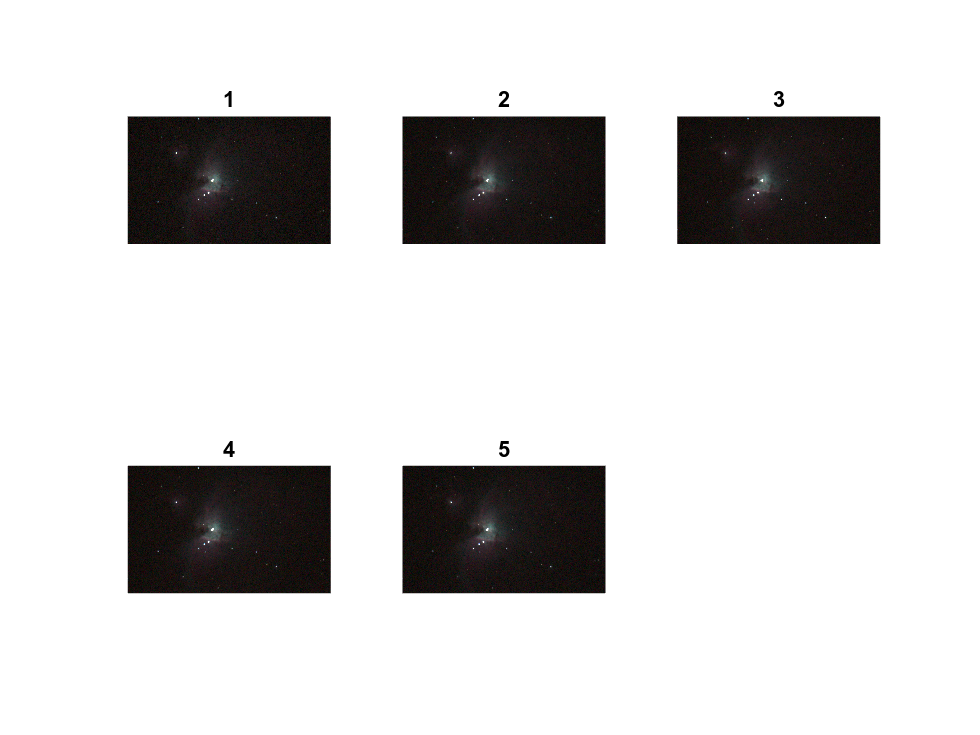

subplot(2,3,1);
imshow(img1), title("1");
subplot(2,3,2);
imshow(img2), title("2");
subplot(2,3,3);
imshow(img3), title("3");
subplot(2,3,4);
imshow(img4), title("4");
subplot(2,3,5);
imshow(img5), title("5");

Taking average of these images

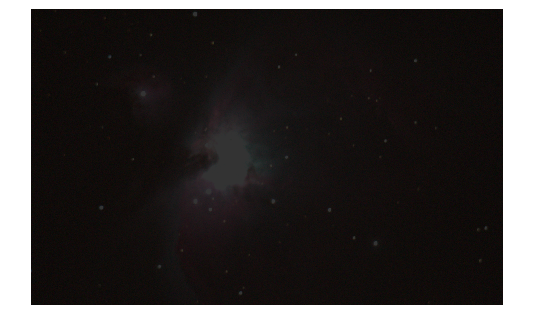

avgImg = (img1 + img2 + img3 + img4)/5;
imshow(avgImg)

Note that the output is not as expected

This is because uint8 addition doesn't work as normal addition, when we add 200 + 200 it becomes 255 (the max value) and dividing the addition result to 5 leads to intensity value 51

uint8(200) + uint8(200)

ans = uint8
   255


So, I'm gonna use `im2double(img) `for valid average, `im2double(img) `converts the values to be in the range [0,1]

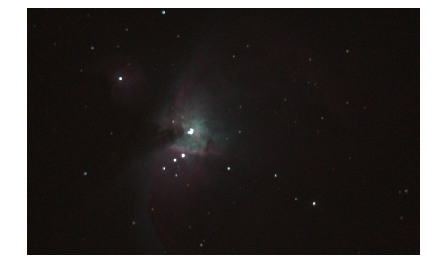

avgImgDouble = (im2double(img1) + im2double(img2) ...
    + im2double(img3) + im2double(img4) + im2double(img5))/5;
imshow(avgImgDouble)

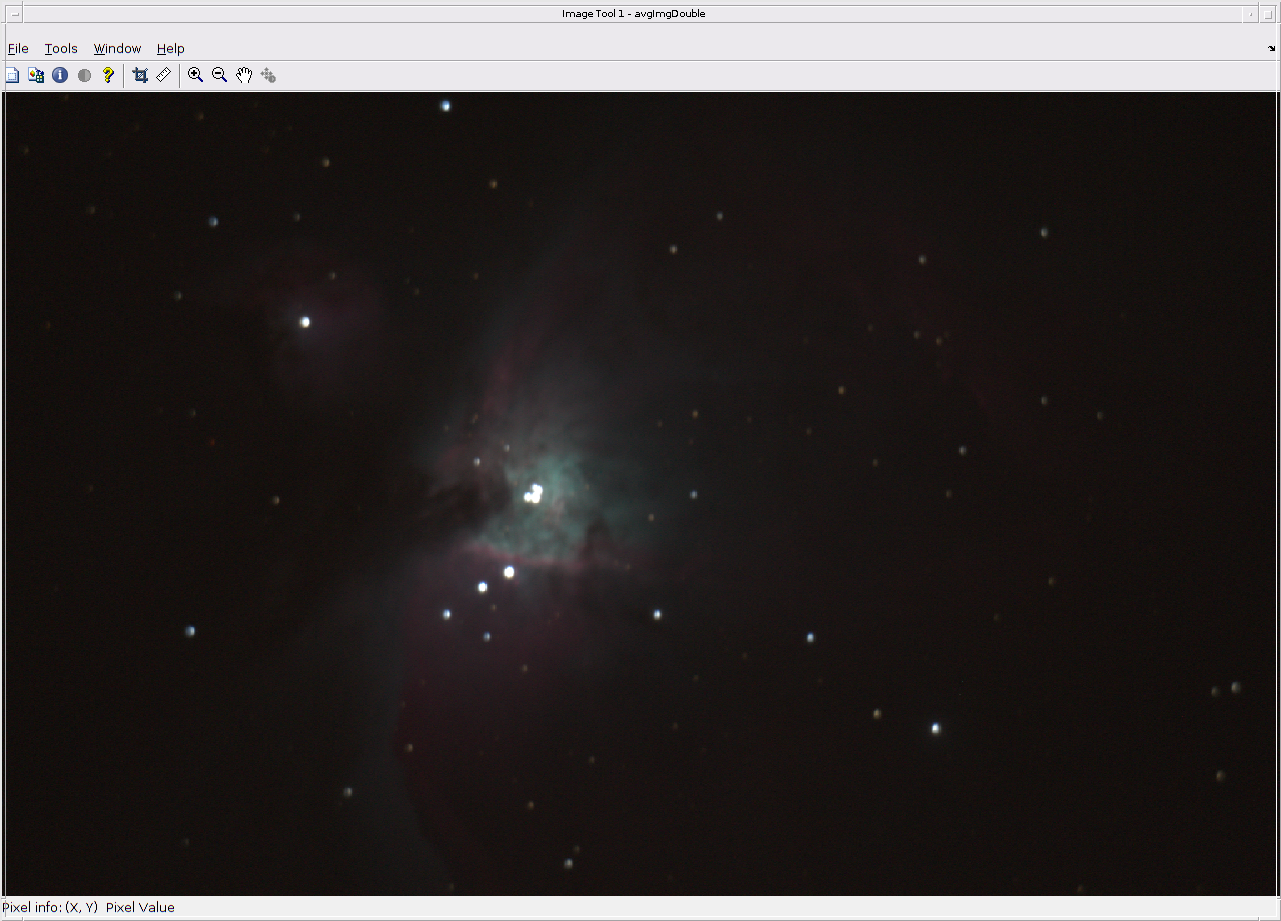

imtool(avgImgDouble)

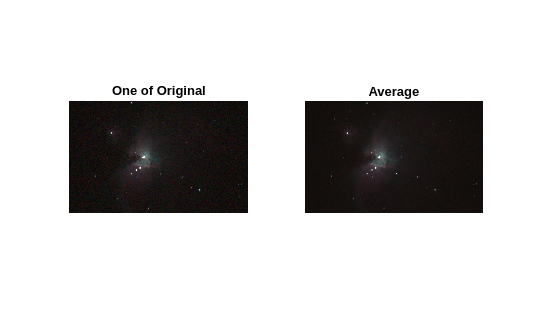

subplot(1,2,1);
imshow(img1), title("One of Original");
subplot(1,2,2);
imshow(avgImgDouble), title("Average");

open images in image tool window and then observe to see the changes clearly

`im2double(img) `rescales the img to [0,1]

pixel_11 = avgImgDouble(1,1)

pixel_11 =    0.011764705882353
